# Workflow DES + Agua

**1. Importar los datos de densidad**

Dens_Mal=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Dens_Maline","VariableNamingRule","preserve")

Dens_Mal = 119×10 table
        DES            Set Type           Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Density(kg.m-3)    Density(g.cm-3)        Reference        DES mole fraction
    ___________    ________________    _____________    __________________    ________________    ______________    _______________    _______________    _________________    _________________

    {'ChCl-MA'}    {'Experimental'}    {'DES+Water'}           0.9                  0.1               303.2             1014.5             1.0145         {'(Hsieh, 2012)'}           NaN       
    {'ChCl-MA'}    {'Experimental'}    {'DES+Water'}    

Gráfica de datos de densidad

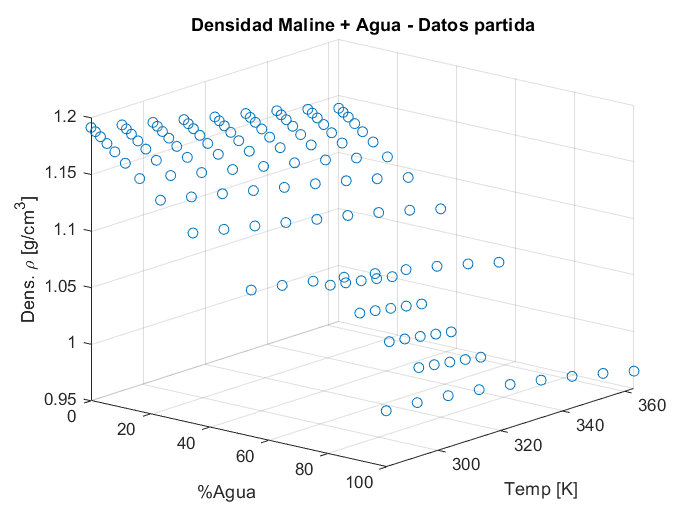

Masa_H2O_Mal=Dens_Mal.Mass_percent_Water*100;
Temp_Mal=Dens_Mal.("Temperature(K)");
Rho_Mal=Dens_Mal.("Density(g.cm-3)");
figure, plot3(Masa_H2O_Mal,Temp_Mal,Rho_Mal,'o');
title('Densidad Maline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento

data1=[Masa_H2O_Mal,Temp_Mal,Rho_Mal];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 119
       NumTestSets: 1
         TrainSize: 96
          TestSize: 23

Datos de entrenamiento

idx_train=training(particion);
train_data_dens1=data1(idx_train,:)

train_data_dens1 =    90.0000  303.2000    1.0145
   90.0000  308.2000    1.0127
   90.0000  313.2000    1.0107
   90.0000  318.2000    1.0086
   80.0000  303.2000    1.0316
   80.0000  313.2000    1.0275
   80.0000  318.2000    1.0252
   80.0000  323.2000    1.0228
   70.0000  303.2000    1.0510
   70.0000  308.2000    1.0488



Masa_H2O_Eth_train=train_data_dens1(:,1);
Temp_Eth_train=train_data_dens1(:,2);
Rho_Eth_train=train_data_dens1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_dens1=data1(idx_test,:)

test_data_dens1 =    90.0000  323.2000    1.0063
   80.0000  308.2000    1.0296
   60.0000  323.2000    1.0599
  100.0000  323.1500    0.9881
  100.0000  343.1500    0.9778
  100.0000  353.1500    0.9717
   54.2623  293.1500    1.0750
   54.2623  333.1500    1.0541
   34.5272  343.1500    1.0843
   23.5285  293.1500    1.1352



Masa_H2O_Eth_test=test_data_dens1(:,1);
Temp_Eth_test=test_data_dens1(:,2);
Rho_Eth_test=test_data_dens1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
regresion1 = fitlm(predictores_train,Rho_Eth_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)         1.3642      0.005247        260    6.7693e-135
    x1               -0.001809    1.1956e-05     -151.3    4.4022e-113
    x2             -0.00062128    1.6065e-05    -38.673     4.1407e-59


Number of observations: 96, Error degrees of freedom: 93
Root Mean Squared Error: 0.00373
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 1.16e+04, p-value = 3.25e-112

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación:')

Ecuación:

fprintf('Densidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Densidad= 1.3642+(-0.0018)*%Agua+(-0.0006)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Eth_train),max(Masa_H2O_Eth_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Eth_train),max(Temp_Eth_train))

Rango de temperatura: 283.15 K - 363.15 K

Ajuste del modelo

x1fit=min(Masa_H2O_Eth_train):2:max(Masa_H2O_Eth_train);
x2fit=min(Temp_Eth_train):1:max(Temp_Eth_train);
[X1fit,X2fit]=meshgrid(x1fit,x2fit);

Y1fit=coef1+coef2*X1fit+coef3*X2fit;




Gráfica 3D

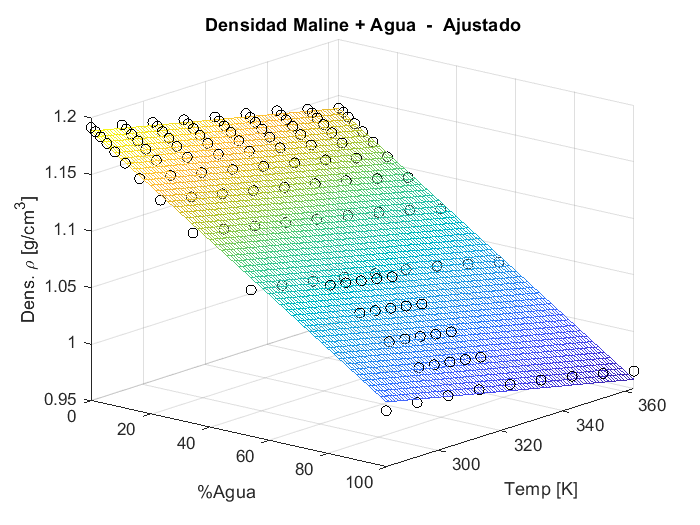

figure, plot3(Masa_H2O_Mal,Temp_Mal,Rho_Mal,'ok'); hold on,
mesh(X1fit,X2fit,Y1fit,'FaceAlpha','0.25'), hold off
title('Densidad Maline + Agua  -  Ajustado'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**4. Analisis de residuos del conjunto de entrenamiento**

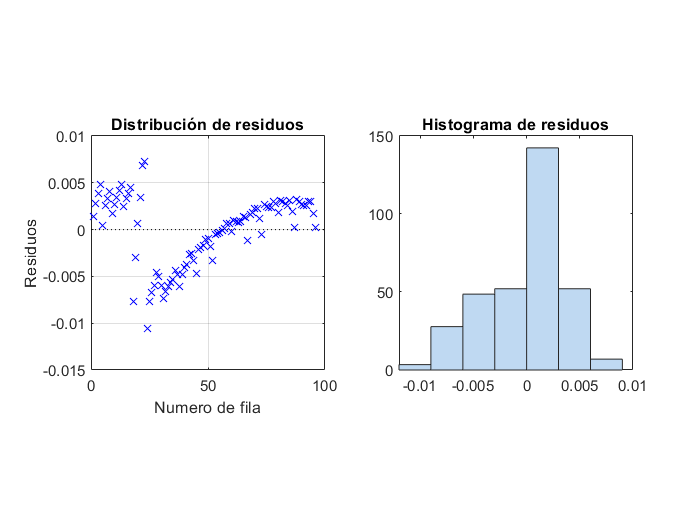

subplot(1,2,1)
plotResiduals(regresion1,'caseorder'),
title('Distribución de residuos'), xlabel('Numero de fila'),
ylabel('Residuos'), grid on, axis square
subplot(1,2,2)
plotResiduals(regresion1), title('Histograma de residuos'), axis square

El histograma muestra que los residuos están ligeramente sesgados a la derecha.

**5. Evaluación Datos de Prueba**

Grafica comparacion datos de prueba

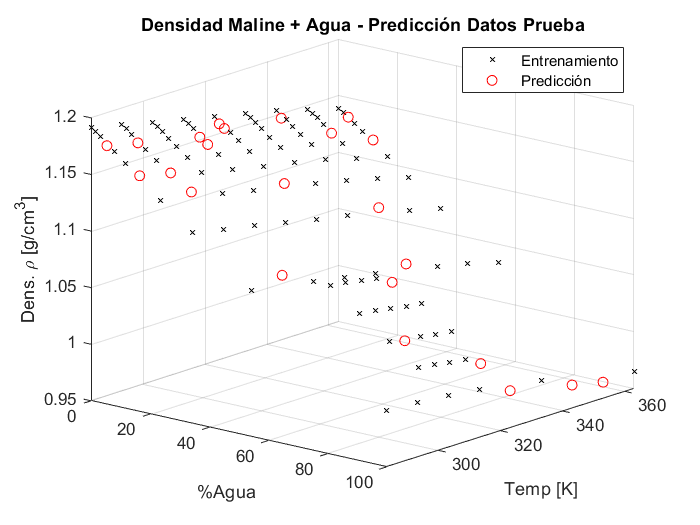

Y1_test=predict(regresion1,[Masa_H2O_Eth_test Temp_Eth_test]);
%Y1_test es la predicción con los datos de prueba
figure, plot3(Masa_H2O_Eth_train,Temp_Eth_train,Rho_Eth_train,'xk','MarkerSize',4)
hold on;
plot3(Masa_H2O_Eth_test,Temp_Eth_test,Y1_test,'or');
title('Densidad Maline + Agua - Predicción Datos Prueba'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
legend('Entrenamiento','Predicción',"Location","best")
view([40 20])

Graficas de residuos de los datos de prueba

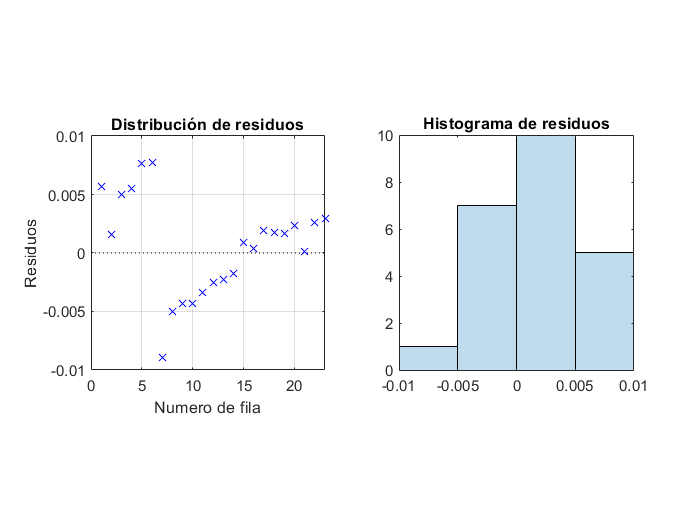

residuos_test=Rho_Eth_test-Y1_test;
subplot(1,2,1)
plot([0:length(Y1_test)],zeros*[0:length(Y1_test)],':k'), hold on,
plot(residuos_test,'xb'), title('Distribución de residuos'),
xlabel('Numero de fila'), ylabel('Residuos'),
grid on, hold off, axis square
subplot(1,2,2)
histogram(residuos_test,'FaceAlpha',0.25),
title('Histograma de residuos'), axis square